# Principal Component Analysis of EEG data per channel with different filtering methods

% This script performs PCA on EEG data across different conditions and filtering methods
clear;
close all;

%% Set paths based on available drives
if exist('H:\', 'dir')  % Computer 1
    input_base_path = 'H:\My Drive\Data\New Data\EEG epoched';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')  % Computer 2
    input_base_path = 'G:\My Drive\Data\New Data\EEG epoched';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

%% Define analysis parameters
% Define conditions, subjects and channels
conditions = {'BLA', 'BLT', 'P1', 'P2', 'P3'};
subjects = {'BOS2', 'BOS3', 'BOS5', 'BOS6', 'BOS7', 'BOS8', 'BOS9', 'BOS10', ...
    'BOS11', 'BOS12', 'BOS13', 'BOS15', 'BOS16', 'BOS17'};
channels = {'F3', 'C3'};

% Define number of PCs to extract
num_pcs = 32;

% Define filtering parameters
alpha_band = [8 12];  % Alpha band (8-12 Hz)
beta_band = [13 30];  % Beta band (13-30 Hz)

% Create output directory
output_path_perChannel = fullfile(output_path, 'pca_per_channel');
if ~exist(output_path_perChannel, 'dir')
    mkdir(output_path_perChannel);
end


## Initialize results structures for plotting

% We'll store PC results for each filtering type, condition, and channel
all_results = struct();
for cond_idx = 1:length(conditions)
    condition = conditions{cond_idx};
    all_results.(condition) = struct();
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        all_results.(condition).(channel) = struct();
        all_results.(condition).(channel).unfiltered = [];
        all_results.(condition).(channel).beta = [];
        all_results.(condition).(channel).alpha = [];
        all_results.(condition).(channel).deltaEEG = [];
    end
end

% Initialize structures to store PCA coefficients and scores across subjects
all_coeff = struct();
all_scores = struct();
for cond_idx = 1:length(conditions)
    condition = conditions{cond_idx};
    all_coeff.(condition) = struct();
    all_scores.(condition) = struct();
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        all_coeff.(condition).(channel) = struct();
        all_scores.(condition).(channel) = struct();
        
        % Initialize arrays to store coefficients and scores for each subject
        all_coeff.(condition).(channel).unfiltered = cell(length(subjects), 1);
        all_coeff.(condition).(channel).beta = cell(length(subjects), 1);
        all_coeff.(condition).(channel).alpha = cell(length(subjects), 1);
        all_coeff.(condition).(channel).deltaEEG = cell(length(subjects), 1);
        
        all_scores.(condition).(channel).unfiltered = cell(length(subjects), 1);
        all_scores.(condition).(channel).beta = cell(length(subjects), 1);
        all_scores.(condition).(channel).alpha = cell(length(subjects), 1);
        all_scores.(condition).(channel).deltaEEG = cell(length(subjects), 1);
    end
end

% Store time point information
time_info = struct();

## Main analysis loop

%% Main analysis loop
% Loop over each condition
for cond_idx = 1:length(conditions)
    condition = conditions{cond_idx};
    fprintf('Processing condition: %s\n', condition);

    % Set excel file path for P2 and P3 conditions if needed
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_base_path, 'Indexes for P2.xlsx');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_base_path, 'Indexes for P3.xlsx');
    else
        excel_file_path = '';
    end

    % Set condition-specific paths
    condition_input_path = fullfile(input_base_path, condition);
    condition_output_path = fullfile(output_path_perChannel, condition);
    
    % Create output directory if it doesn't exist
    if ~exist(condition_output_path, 'dir')
        mkdir(condition_output_path);
    end
    
    % Initialize arrays to collect data across subjects
    all_subjects_data = struct();
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        all_subjects_data.(channel) = struct();
        all_subjects_data.(channel).unfiltered = [];
        all_subjects_data.(channel).beta = [];
        all_subjects_data.(channel).alpha = [];
        all_subjects_data.(channel).deltaEEG = [];
        all_subjects_data.(channel).time_indices = [];
        all_subjects_data.(channel).trial_indices = [];
    end
    
    % Get all .set files in the directory
    set_files = dir(fullfile(condition_input_path, '*.set'));
    
    % Create a cell array to store all subject data for later combining
    subject_data_cell = cell(length(subjects), 1);
    
    % Process each subject's data in parallel
    parfor sub_idx = 1:length(subjects)
        % Initialize local data structure for this subject
        local_subject_data = struct();
        for ch_idx = 1:length(channels)
            channel = channels{ch_idx};
            local_subject_data.(channel) = struct();
            local_subject_data.(channel).unfiltered = [];
            local_subject_data.(channel).beta = [];
            local_subject_data.(channel).alpha = [];
            local_subject_data.(channel).deltaEEG = [];
            local_subject_data.(channel).time_indices = [];
            local_subject_data.(channel).time_points = [];
            local_subject_data.(channel).num_time_points = [];
            local_subject_data.(channel).trial_indices = [];
        end
        
        subject = subjects{sub_idx};
        
        % Cannot use fprintf inside parfor - use disp instead
        disp(['  Processing subject: ', subject]);
        
        % Find the file that contains this subject ID
        file_idx = find_subject_file(set_files, subject);
        
        if file_idx == 0
            warning('No matching file found for subject %s in condition %s. Skipping.', subject, condition);
            subject_data_cell{sub_idx} = local_subject_data;  % Store empty result
            continue;
        end
        
        file_path = fullfile(condition_input_path, set_files(file_idx).name);
        disp(['    Using file: ', set_files(file_idx).name]);
           
        try
            % Load EEG data
            EEG = pop_loadset(file_path);
            fs = EEG.srate;  % Sampling rate
            time_vector = EEG.times / 1000;  % Convert to seconds
            % time_vector = EEG.times;  % Keep in msec
            % Use a function to determine epoch_trials based on condition and EEG data
            epoch_trials = get_epoch_trials(condition, EEG.trials);
            
            % Define time windows (this may vary by trial for P2/P3)
            pre_window = [-0.4, 0];  % Pre-stimulus window (-400ms to 0ms)
            
            % For P2 and P3, determine valid trials based on Excel files
            valid_trials = epoch_trials;
            if strcmp(condition, 'P2')
                trials_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
                trials_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
                valid_trials = intersect(epoch_trials, [trials_500ms; trials_2000ms]);
            elseif strcmp(condition, 'P3')
                trials_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
                trials_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
                valid_trials = intersect(epoch_trials, [trials_500ms; trials_missing]);
            end
            
            % Process each channel
            for ch_idx = 1:length(channels)
                channel = channels{ch_idx};
                disp(['    Processing channel: ', channel]);
                
                % Find channel index
                channel_idx = find(strcmp({EEG.chanlocs.labels}, channel));
                if isempty(channel_idx)
                    warning('Channel %s not found. Skipping.', channel);
                    continue;
                end
                
                % Extract data for this channel across all valid trials
                data = EEG.data(channel_idx, :, valid_trials);  % Channel x Time x Trials
                
                % Determine post-window (use the most common case for simplicity)
                if strcmp(condition, 'BLA') || strcmp(condition, 'BLT')
                    post_window = [0, 0.4];  % Post-stimulus window (0ms to +400ms)
                else
                    post_window = [0, 1.020];  % Post-stimulus window (0ms to +1020ms) for P1, most of P2, P3
                end
                
                % Convert time windows to indices
                pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
                post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));
                
                % Combine pre and post indices
                analysis_idx = [pre_idx, post_idx];
                
                % Get data for analysis (time points in analysis window x trials)
                analysis_data = data(:, analysis_idx, :);
                
                % Store time points for visualization
                time_points = time_vector(analysis_idx);
                
                % Reshape data for PCA: time x trials becomes observations
                % We'll reshape to a 2D matrix: time*trials x 1
                reshaped_data = reshape(analysis_data, 1, numel(analysis_data));
                
                % For beta and alpha, apply filtering before reshaping
                
                % Beta filtering
                beta_data = zeros(size(data));
                for tr = 1:size(data, 3)
                    beta_data(:, :, tr) = bandpass(squeeze(data(:, :, tr)), beta_band, fs);
                end
                beta_analysis = beta_data(:, analysis_idx, :);
                reshaped_beta = reshape(beta_analysis, 1, numel(beta_analysis));
                
                % Alpha filtering
                alpha_data = zeros(size(data));
                for tr = 1:size(data, 3)
                    alpha_data(:, :, tr) = bandpass(squeeze(data(:, :, tr)), alpha_band, fs);
                end
                alpha_analysis = alpha_data(:, analysis_idx, :);
                reshaped_alpha = reshape(alpha_analysis, 1, numel(alpha_analysis));
                
                % Delta EEG (spatial filtering)
                if size(EEG.data, 1) > 1 % Only if we have multiple channels
                    % Extract all data for valid trials
                    all_channels_data = EEG.data(:, :, valid_trials);
                    
                    % Apply spatial filtering
                    spatially_filtered_data = subtract_surrounding_channels(all_channels_data, EEG.chanlocs);
                    
                    % Get the spatially filtered data for our channel of interest
                    deltaEEG_data = spatially_filtered_data(channel_idx, :, :);
                    deltaEEG_analysis = deltaEEG_data(:, analysis_idx, :);
                    reshaped_deltaEEG = reshape(deltaEEG_analysis, 1, numel(deltaEEG_analysis));
                else
                    % If only one channel is available, we can't perform spatial filtering
                    warning('Cannot perform spatial filtering with only one channel. Using original signal.');
                    deltaEEG_analysis = analysis_data;
                    reshaped_deltaEEG = reshaped_data;
                end
                
                % Store data for this subject in the local structure
                local_subject_data.(channel).unfiltered = reshaped_data';
                local_subject_data.(channel).beta = reshaped_beta';
                local_subject_data.(channel).alpha = reshaped_alpha';
                local_subject_data.(channel).deltaEEG = reshaped_deltaEEG';
                local_subject_data.(channel).time_indices = analysis_idx;
                local_subject_data.(channel).time_points = time_points;
                local_subject_data.(channel).num_time_points = length(analysis_idx);
                local_subject_data.(channel).trial_indices = valid_trials;
            end
            
        catch ME
            warning('Error processing subject %s: %s', subject, ME.message);
        end
        
        % Store the local data for this subject in the cell array
        subject_data_cell{sub_idx} = local_subject_data;
    end
    
    % Combine all subject data after parallel processing
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        
        % Initialize time indices for the first valid subject we find
        for sub_idx = 1:length(subjects)
            subject_data = subject_data_cell{sub_idx};
            if isfield(subject_data, channel) && isfield(subject_data.(channel), 'time_indices') && ~isempty(subject_data.(channel).time_indices)
                all_subjects_data.(channel).time_indices = subject_data.(channel).time_indices;
                all_subjects_data.(channel).time_points = subject_data.(channel).time_points;
                all_subjects_data.(channel).num_time_points = subject_data.(channel).num_time_points;
                all_subjects_data.(channel).trial_indices = subject_data.(channel).trial_indices;
                break;
            end
        end
        
        % Combine data from all subjects
        for sub_idx = 1:length(subjects)
            subject_data = subject_data_cell{sub_idx};
            
            if isfield(subject_data, channel) && isfield(subject_data.(channel), 'unfiltered') && ~isempty(subject_data.(channel).unfiltered)
                all_subjects_data.(channel).unfiltered = [all_subjects_data.(channel).unfiltered; subject_data.(channel).unfiltered];
                all_subjects_data.(channel).beta = [all_subjects_data.(channel).beta; subject_data.(channel).beta];
                all_subjects_data.(channel).alpha = [all_subjects_data.(channel).alpha; subject_data.(channel).alpha];
                all_subjects_data.(channel).deltaEEG = [all_subjects_data.(channel).deltaEEG; subject_data.(channel).deltaEEG];
            end
        end
    end
    
    % Now perform PCA on the combined data for each channel and filtering method
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        
        % Check if we have data for this channel
        if ~isfield(all_subjects_data, channel) || ~isfield(all_subjects_data.(channel), 'unfiltered') || isempty(all_subjects_data.(channel).unfiltered)
            warning('No data found for channel %s in condition %s. Skipping.', channel, condition);
            continue;
        end
        
        % Perform PCA for each filtering method
        % Unfiltered
        [coeff_unfiltered, score_unfiltered, ~, ~, explained_unfiltered] = pca(all_subjects_data.(channel).unfiltered);
        
        % Beta
        [coeff_beta, score_beta, ~, ~, explained_beta] = pca(all_subjects_data.(channel).beta);
        
        % Alpha
        [coeff_alpha, score_alpha, ~, ~, explained_alpha] = pca(all_subjects_data.(channel).alpha);
        
        % DeltaEEG (spatial filtering)
        [coeff_deltaEEG, score_deltaEEG, ~, ~, explained_deltaEEG] = pca(all_subjects_data.(channel).deltaEEG);
        
        % Store results for plotting
        all_results.(condition).(channel).unfiltered = explained_unfiltered(1:min(num_pcs, length(explained_unfiltered)));
        all_results.(condition).(channel).beta = explained_beta(1:min(num_pcs, length(explained_beta)));
        all_results.(condition).(channel).alpha = explained_alpha(1:min(num_pcs, length(explained_alpha)));
        all_results.(condition).(channel).deltaEEG = explained_deltaEEG(1:min(num_pcs, length(explained_deltaEEG)));
        
        % Store more detailed information for heatmap visualization
        if ~isfield(all_results.(condition).(channel), 'details')
            all_results.(condition).(channel).details = struct();
        end
        
        % Store scores and metadata for heatmap creation
        all_results.(condition).(channel).details.unfiltered = struct(...
            'coeff', coeff_unfiltered, ...
            'scores', score_unfiltered, ...
            'explained', explained_unfiltered, ...
            'num_time_points', all_subjects_data.(channel).num_time_points, ...
            'time_points', all_subjects_data.(channel).time_points, ...
            'num_trials', length(all_subjects_data.(channel).trial_indices));
        
        all_results.(condition).(channel).details.beta = struct(...
            'coeff', coeff_beta, ...
            'scores', score_beta, ...
            'explained', explained_beta, ...
            'num_time_points', all_subjects_data.(channel).num_time_points, ...
            'time_points', all_subjects_data.(channel).time_points, ...
            'num_trials', length(all_subjects_data.(channel).trial_indices));
        
        all_results.(condition).(channel).details.alpha = struct(...
            'coeff', coeff_alpha, ...
            'scores', score_alpha, ...
            'explained', explained_alpha, ...
            'num_time_points', all_subjects_data.(channel).num_time_points, ...
            'time_points', all_subjects_data.(channel).time_points, ...
            'num_trials', length(all_subjects_data.(channel).trial_indices));
        
        all_results.(condition).(channel).details.deltaEEG = struct(...
            'coeff', coeff_deltaEEG, ...
            'scores', score_deltaEEG, ...
            'explained', explained_deltaEEG, ...
            'num_time_points', all_subjects_data.(channel).num_time_points, ...
            'time_points', all_subjects_data.(channel).time_points, ...
            'num_trials', length(all_subjects_data.(channel).trial_indices));
        
        % Save PCA results
        save(fullfile(condition_output_path, [channel '_pca_results.mat']), ...
            'coeff_unfiltered', 'score_unfiltered', 'explained_unfiltered', ...
            'coeff_beta', 'score_beta', 'explained_beta', ...
            'coeff_alpha', 'score_alpha', 'explained_alpha', ...
            'coeff_deltaEEG', 'score_deltaEEG', 'explained_deltaEEG', ...
            'all_subjects_data');
    end
end

Processing condition: BLA


  Processing subject: BOS10
    Using file: binepochs filtered ICArej BLAAvgBOS10.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...
  Processing subject: BOS8
    Using file: binepochs filtered ICArej BLAAvgBOS8.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...
  Processing subject: BOS6
    Using file: binepochs filtered ICArej BLAAvgBOS6.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...
  Processing subject: BOS7
    Using file: binepochs filtered ICArej BLAAvgBOS7.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...
  Processing subject: BOS9
    Using file: binepochs filtered ICArej BLAAvgBOS9.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...
  

Processing condition: BLT


  Processing subject: BOS10
    Using file: binepochs filtered ICArej BLTAvgBOS10.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...
  Processing subject: BOS8
    Using file: binepochs filtered ICArej BLTAvgBOS8.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...
  Processing subject: BOS6
    Using file: binepochs filtered ICArej BLTAvgBOS6.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...
  Processing subject: BOS7
    Using file: binepochs filtered ICArej BLTAvgBOS7.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...
  Processing subject: BOS9
    Using file: binepochs filtered ICArej BLTAvgBOS9.set
pop_loadset(): loadi

Processing condition: P1


  Processing subject: BOS10
    Using file: binepochs filtered ICArej P1AvgBOS10.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...
  Processing subject: BOS8
    Using file: binepochs filtered ICArej P1AvgBOS8.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...
  Processing subject: BOS6
    Using file: binepochs filtered ICArej P1AvgBOS6.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...
  Processing subject: BOS7
    Using file: binepochs filtered ICArej P1AvgBOS7.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...
  Processing subject: BOS9
    Using file: binepochs filtered ICArej P1AvgBOS9.set
pop_loadset(): loading file G:\My

Processing condition: P2


  Processing subject: BOS10
    Using file: binepochs filtered ICArej P2AvgBOS10.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...
  Processing subject: BOS8
    Using file: binepochs filtered ICArej P2AvgBOS8.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...
  Processing subject: BOS6
    Using file: binepochs filtered ICArej P2AvgBOS6.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...
  Processing subject: BOS7
    Using file: binepochs filtered ICArej P2AvgBOS7.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...
  Processing subject: BOS9
    Using file: binepochs filtered ICArej P2AvgBOS9.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...
  Processing subj

Processing condition: P3


  Processing subject: BOS10
    Using file: binepochs filtered ICArej P3AvgBOS10.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...
  Processing subject: BOS8
    Using file: binepochs filtered ICArej P3AvgBOS8.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...
  Processing subject: BOS6
    Using file: binepochs filtered ICArej P3AvgBOS6.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...
  Processing subject: BOS7
    Using file: binepochs filtered ICArej P3AvgBOS7.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...
  Processing subject: BOS9
    Using file: binepochs filtered ICArej P3AvgBOS9.set
pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...
  Processing subj


% Helper function to find the file for a specific subject
function file_idx = find_subject_file(set_files, subject_id)
    file_idx = 0;
    
    for i = 1:length(set_files)
        filename = set_files(i).name;
        
        % Split the filename by spaces and check if the subject ID is present
        % in the last part of the name (or anywhere in the name)
        parts = strsplit(filename, ' ');
        
        % First try to find an exact match in the last part (e.g., "sub01")
        if length(parts) > 0 && contains(parts{end}, subject_id)
            file_idx = i;
            return;
        end
        
        % If no match in the last part, check if the subject ID appears anywhere in the filename
        if contains(filename, subject_id)
            file_idx = i;
            return;
        end
    end
end

## Generate final plots

%% Generate heatmap visualizations
% For each channel and condition, create heatmaps of PCs explaining 85% variance
filter_types = {'unfiltered', 'beta', 'alpha', 'deltaEEG'};
filter_titles = {'Unfiltered Signal', 'Beta Band (13-30 Hz)', 'Alpha Band (8-12 Hz)', 'Spatially Filtered (Delta EEG)'};

% This part cannot be parallelized as figure creation is not thread-safe
for ch_idx = 1:length(channels)
    channel = channels{ch_idx};
    
    for cond_idx = 1:length(conditions)
        condition = conditions{cond_idx};
        
        % Check if we have data for this condition and channel
        if ~isfield(all_results, condition) || ~isfield(all_results.(condition), channel)
            warning('No data for condition %s, channel %s. Skipping.', condition, channel);
            continue;
        end
        
        % Create figure with subplots
        figure('Name', ['PCA Heatmaps - ' condition ' - Channel ' channel], ...
               'Position', [100, 100, 1600, 900]);
        
        % For each filtering method
        for f_idx = 1:length(filter_types)
            filter_type = filter_types{f_idx};
            
            % Skip if no data or details not available
            if ~isfield(all_results.(condition).(channel), 'details') || ...
               ~isfield(all_results.(condition).(channel).details, filter_type)
                warning('No data for filter %s in condition %s, channel %s. Skipping.', filter_type, condition, channel);
                continue;
            end
            
            details = all_results.(condition).(channel).details.(filter_type);
            explained = details.explained;
            
            % Find how many PCs are needed to explain 85% variance
            cum_explained = cumsum(explained);
            num_pcs_85percent = find(cum_explained >= 85, 1, 'first');
            if isempty(num_pcs_85percent)
                num_pcs_85percent = length(explained); % Use all if 85% not reached
            end
            
            % Get PC scores
            scores = details.scores(:, 1:num_pcs_85percent);
            
            % Check if we have the necessary fields
            if ~isfield(details, 'num_time_points') || ~isfield(details, 'num_trials') || ...
               isempty(details.num_time_points) || details.num_time_points == 0 || ...
               isempty(details.num_trials) || details.num_trials == 0
                warning('Missing time points or trials info for %s in condition %s, channel %s. Skipping.', filter_type, condition, channel);
                continue;
            end
            
            num_time_points = details.num_time_points;
            num_trials = details.num_trials;
            
            % Time-based heatmap (first column)
            subplot(4, 2, (f_idx-1)*2 + 1);
            
            % Reshape scores to separate time and trials
            % Original scores matrix is (time_points * trials) x PCs
            % We need to average across trials to get time x PCs
            scores_reshaped = reshape(scores, num_time_points, [], num_pcs_85percent);
            time_avg_scores = squeeze(mean(scores_reshaped, 2)); % Average across trials
            
            % Handle case where only one PC is needed (squeeze might remove dimension)
            if num_pcs_85percent == 1
                time_avg_scores = time_avg_scores(:);  % Ensure it's a column vector
            end
            
            % Create heatmap
            imagesc(time_avg_scores);
            
            % Add labels and title
            title([filter_titles{f_idx} ' - Time vs PCs']);
            xlabel(['PCs (explaining 85% variance, n=' num2str(num_pcs_85percent) ')']);
            ylabel('Time');
            
            % Add colorbar
            colorbar;
            
            % Set custom y-tick labels if time points are available
            if isfield(details, 'time_points') && ~isempty(details.time_points)
                time_points = details.time_points;
                num_ticks = min(10, length(time_points)); % Limit to 10 ticks for readability
                tick_indices = round(linspace(1, length(time_points), num_ticks));
                tick_times = time_points(tick_indices);
                % Format time labels with 2 decimal places
                tick_labels = arrayfun(@(x) sprintf('%.2f', x), tick_times, 'UniformOutput', false);
                set(gca, 'YTick', tick_indices, 'YTickLabel', tick_labels);
            end
            
            % Trial-based heatmap (second column)
            subplot(4, 2, (f_idx-1)*2 + 2);
            
            % Reshape scores to average across time points
            trial_avg_scores = squeeze(mean(scores_reshaped, 1)); % Average across time
            
            % Handle case where only one PC is needed (squeeze might remove dimension)
            if num_pcs_85percent == 1
                trial_avg_scores = trial_avg_scores(:)';  % Ensure it's a row vector
            end
            
            % Create heatmap
            imagesc(trial_avg_scores);
            
            % Add labels and title
            title([filter_titles{f_idx} ' - Trial vs PCs']);
            xlabel(['PCs (explaining 85% variance, n=' num2str(num_pcs_85percent) ')']);
            ylabel('Trial');
            
            % Add colorbar
            colorbar;
        end
        
        % Adjust figure properties
        sgtitle([condition ' - Channel ' channel ' - PCA Heatmaps'], 'FontSize', 14, 'FontWeight', 'bold');
        
        % Save the figure
        saveas(gcf, fullfile(output_path_perChannel, ['PCA_Heatmaps_' condition '_Channel_' channel '.fig']));
        saveas(gcf, fullfile(output_path_perChannel, ['PCA_Heatmaps_' condition '_Channel_' channel '.png']));
        
        % Close the figure to free memory
        close(gcf);
    end
end

fprintf('Heatmap visualization complete! Results saved to: %s\n', output_path_perChannel);

Heatmap visualization complete! Results saved to: C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel


fprintf('Analysis complete! Results saved to: %s\n', output_path_perChannel);

Analysis complete! Results saved to: C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\pca_per_channel


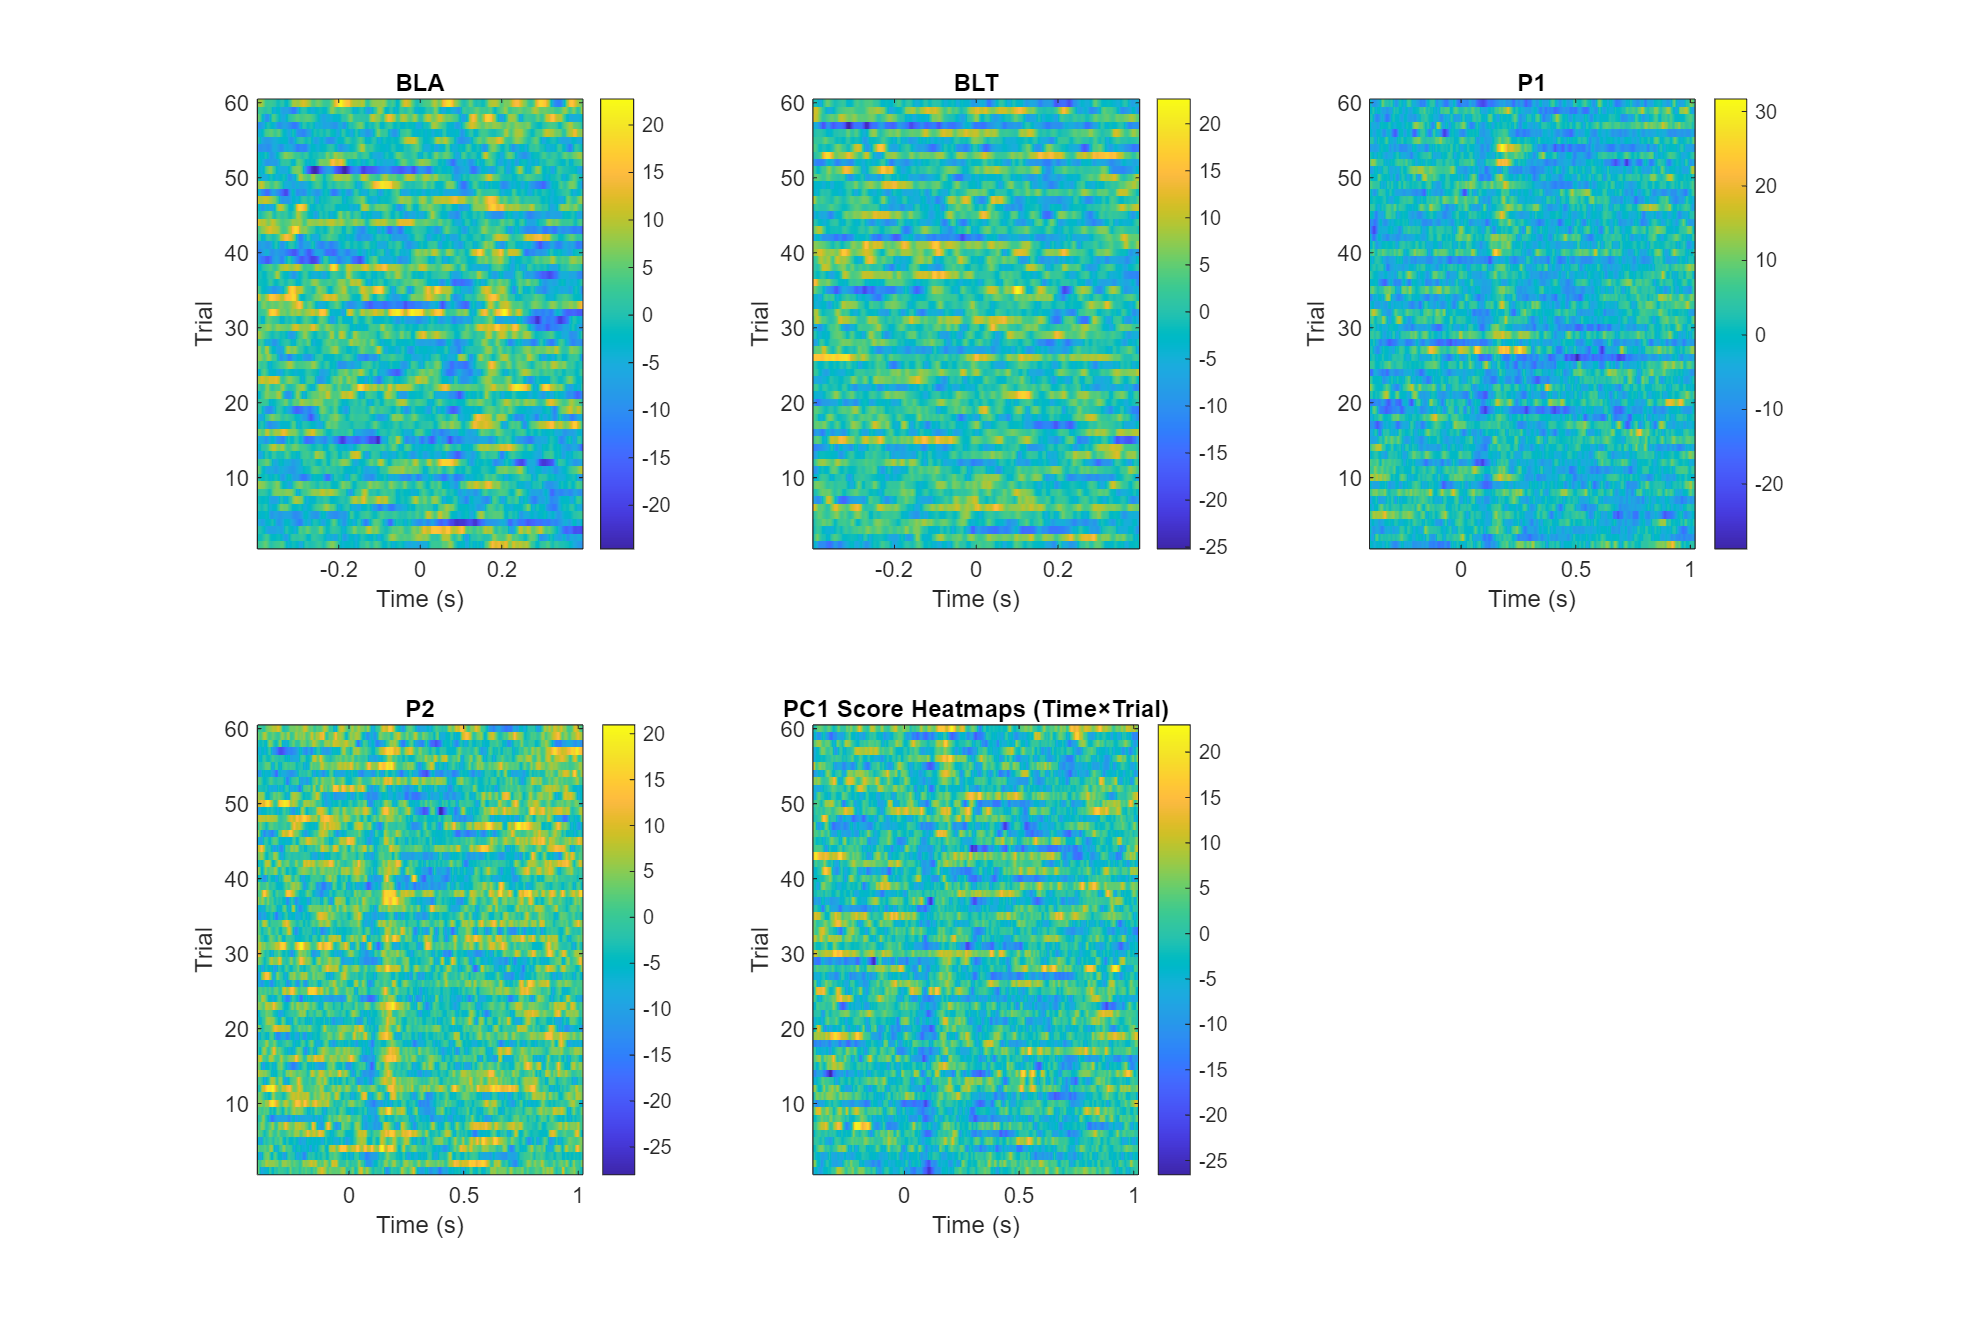

%% === REPLACE ALL EXISTING "Generate heatmap visualizations" SECTION WITH THIS ===

% Which PC to visualize
pc_idx = 1;  

% Pre- and post-stimulus index vectors (must match those used in your PCA)
pre_idx  = find(time_points >= -0.4  & time_points <= 0);    % e.g. –400…0 ms
post_idx = find(time_points >=  0    & time_points <= 0.4);  % e.g.  0…+400 ms

%% 1) Score heatmaps (time × trial) for each condition, PC1
figure('Name','PC1 Score: Time vs Trial','Position',[200 200 1200 800]);
for iCond = 1:length(conditions)
    cond = conditions{iCond};
    details = all_results.(cond).(channels{1}).details.unfiltered;  
      % unfiltered → or pick whichever filter type you want

    scores = details.scores(:,pc_idx);                    % (time_points * trials) × 1
    T = details.num_time_points;
    N = details.num_trials;
    S = reshape(scores, T, N,[]);                            % time × trial
    S1 = S(:,:,1);
    subplot(2,3,iCond);
    imagesc(details.time_points, 1:N, S1');               % trials on y, time on x
    axis xy;                                             % origin bottom-left
    title(sprintf('%s', cond));
    xlabel('Time (s)');   ylabel('Trial');
    colorbar;
end
title(sprintf('PC%d Score Heatmaps (Time×Trial)',pc_idx));


%% 2) Mean ± SD of PC coefficients pre vs post
% Collect coeffs across conditions
all_pre  = [];
all_post = [];
for iCond = 1:length(conditions)
    cond = conditions{iCond};
    C = all_results.(cond).(channels{1}).details.unfiltered.explained; % if you stored coeffs, replace with coeffs
    % If you saved actual coeff matrix in details.coeff(:,pc_idx), use that:
    coeffs = all_results.(cond).(channels{1}).details.unfiltered.coeff(:,pc_idx);
    all_pre(iCond,:)  = coeffs(pre_idx);
    all_post(iCond,:) = coeffs(post_idx);
end

Index exceeds the number of array elements. Index must not exceed 1.


mean_pre  = mean(all_pre,1);
std_pre   = std(all_pre,0,1);
mean_post = mean(all_post,1);
std_post  = std(all_post,0,1);

figure('Name','PC Coefficients Pre vs Post','Position',[300 300 800 600]);
subplot(2,1,1);
errorbar(mean_pre, std_pre, 'LineWidth',1.5);
title('Pre-stimulus PC Coefficients');
xlabel('Time Sample (pre)'); ylabel(sprintf('PC%d Coeff',pc_idx));

subplot(2,1,2);
errorbar(mean_post, std_post, 'LineWidth',1.5);
title('Post-stimulus PC Coefficients');
xlabel('Time Sample (post)'); ylabel(sprintf('PC%d Coeff',pc_idx));

%% 3) F3 vs C3: overlay PC1 score time-series across conditions
figure('Name','F3 vs C3: PC1 Score Time Series','Position',[400 400 1000 600]);
for chIdx = 1:length(channels)
    chan = channels{chIdx};
    subplot(2,1,chIdx);
    hold on;
    for iCond = 1:length(conditions)
        cond   = conditions{iCond};
        det    = all_results.(cond).(chan).details.unfiltered;
        scores = det.scores(:,pc_idx);
        T      = det.num_time_points;
        N      = det.num_trials;
        S      = reshape(scores, T, N);       % time × trial
        tseries = mean(S,2);                  % average across trials
        plot(det.time_points, tseries, 'DisplayName', cond, 'LineWidth',1.2);
    end
    hold off;
    title(sprintf('%s – PC%d Score (avg over trials)', chan, pc_idx));
    xlabel('Time (s)'); ylabel('Score');
    legend('Location','best');
end
suptitle('Comparison: F3 vs C3 PC1 Score across Conditions');

%% === END REPLACEMENT ===

%% 4×5 Grid: PC1 Score Heatmaps by Signal Type and Condition
pc_idx = 1;             % principal component to plot
channel = 'F3';         % change to 'C3' if desired

filter_types  = {'unfiltered','beta','alpha','deltaEEG'};
filter_titles = {'Unfiltered','Beta (13–30 Hz)','Alpha (8–12 Hz)','Delta EEG'};

figure('Name','Signal × Condition PC1 Heatmaps','Position',[100 100 2000 1200]);
for f = 1:length(filter_types)
    for c = 1:length(conditions)
        cond = conditions{c};
        det  = all_results.(cond).(channel).details.(filter_types{f});
        
        % reshape PC1 scores into time×trial
        T = det.num_time_points;
        N = det.num_trials;
        S = reshape(det.scores(:,pc_idx), T, N,[]);
        
        % subplot index
        idx = (f-1)*length(conditions) + c;
        subplot(length(filter_types), length(conditions), idx);
        
        imagesc(det.time_points, 1:N, S');  % trials on y, time on x
        axis xy;
        if f==1
            title(cond,'FontWeight','bold');
        end
        if c==1
            ylabel(filter_titles{f}, 'FontWeight','bold');
        else
            set(gca,'YTick',[]);
        end
        
        if f==length(filter_types)
            xlabel('Time (s)');
        else
            set(gca,'XTick',[]);
        end
        colormap('hot');
    end
end

% shared colorbar on right
h = colorbar('Position',[0.93 0.11 0.02 0.815]);
ylabel(h, sprintf('PC%d Score',pc_idx));

suptitle(sprintf('PC%d Score Heatmaps: Signals (rows) × Conditions (cols), Channel %s', pc_idx, channel));


function epoch_trials = get_epoch_trials(condition, num_trials)
    % Helper function to determine which trials to use based on condition
    if strcmp(condition, 'BLA') || strcmp(condition, 'P1') || strcmp(condition, 'P2') || strcmp(condition, 'P3')
        epoch_trials = 1:2:num_trials;  % Odd epochs
    elseif strcmp(condition, 'BLT')
        epoch_trials = 2:2:num_trials;  % Even epochs
    else
        error('Condition not recognized. Please specify "BLA" or "BLT".');
    end
end

%% Helper function for spatial filtering (Delta EEG)
function filtered_data = subtract_surrounding_channels(data, channel_locations)
    % Subtracts the mean of surrounding channels from each channel
    % 
    % Inputs:
    %   data: EEG data matrix (channels x time x trials)
    %   channel_locations: EEG.chanlocs structure containing channel coordinates
    %
    % Output:
    %   filtered_data: Data with surrounding channel mean subtracted
    
    num_channels = size(data, 1);
    num_timepoints = size(data, 2);
    num_trials = size(data, 3);
    filtered_data = zeros(size(data));
    
    % Extract coordinates for all channels
    if isfield(channel_locations, 'X') && isfield(channel_locations, 'Y') && isfield(channel_locations, 'Z')
        coords = [[channel_locations.X]', [channel_locations.Y]', [channel_locations.Z]'];
    else
        error('Channel locations must contain X, Y, and Z coordinates');
    end
    
    % Calculate Euclidean distances between all channels
    distances = zeros(num_channels, num_channels);
    for i = 1:num_channels
        for j = 1:num_channels
            distances(i,j) = sqrt(sum((coords(i,:) - coords(j,:)).^2));
        end
    end
    
    % Define surrounding channels for each channel
    % You can adjust the threshold to define what "surrounding" means
    threshold = mean(distances(:)) * 0.5; % Adjust this multiplier as needed
    
    for ch = 1:num_channels
        % Find surrounding channels (channels within threshold distance)
        surrounding_idx = find(distances(ch,:) > 0 & distances(ch,:) <= threshold);
        
        if isempty(surrounding_idx)
            warning(['No surrounding channels found for channel ', num2str(ch), '. Keeping original signal.']);
            filtered_data(ch,:,:) = data(ch,:,:);
            continue;
        end
        
        % Calculate mean of surrounding channels
        surrounding_mean = mean(data(surrounding_idx,:,:), 1);
        
        % Subtract surrounding mean from the channel
        filtered_data(ch,:,:) = data(ch,:,:) - surrounding_mean;
    end
end